
X1 = randn (50 ,2) + 1;
X2 = randn (51 ,2) - 1;

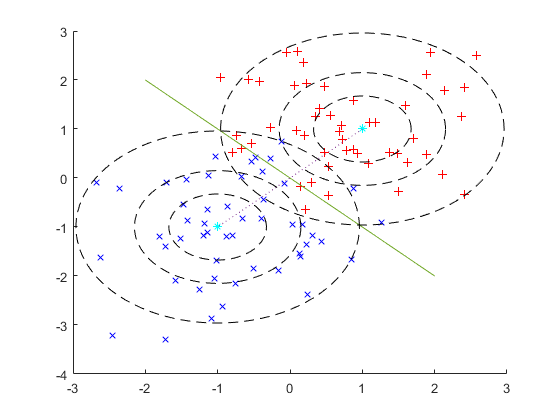

Y1 = ones(50 ,1);
Y2 = -ones(51 ,1);

O1 = [1, 1];
O2 = [-1, -1];
M = (O1 + O2)/2;
V = O1 - O2;
VN = [-V(2), V(1)];
figure;
hold on;
% axis equal;
plot(X1(:,1), X1(:,2), 'r+');
plot(X2(:,1), X2(:,2), 'bx');
plot([O1(1), O2(1)], [O1(2), O2(2)],'c*');
% p10t(02(1), 02(2), 'c*');
% p10t(M(1), M(2). 'm*');
plot([O1(1) O2(1)],[O1(2) O2(2)],':')
plot([M(1)+VN(1) M(1)-VN(1)],[M(2)+VN(2) M(2)-VN(2)]);

for r = [norminv(0.75,0,1), norminv(0.875,0,1), norminv(0.975,0,1)]
    theta = linspace(0,2*pi);
    x = r*cos(theta) + 1;
    y = r*sin(theta) + 1;
    plot(x,y,'--k');
end

for r = [norminv(0.75,0,1), norminv(0.875,0,1), norminv(0.975,0,1)]
    theta = linspace(0,2*pi);
    x = r*cos(theta) - 1;
    y = r*sin(theta) - 1;
    plot(x,y,'--k');
end